# EE6133 : Multirate Digital Signal Processing

# Assignment 2a

## Name : ANIRUDH B S (EE21B019)

## Magnitude Response of the Unprocessed Signals

Firstly, we will process the Speech signal sampled at 8kHz.

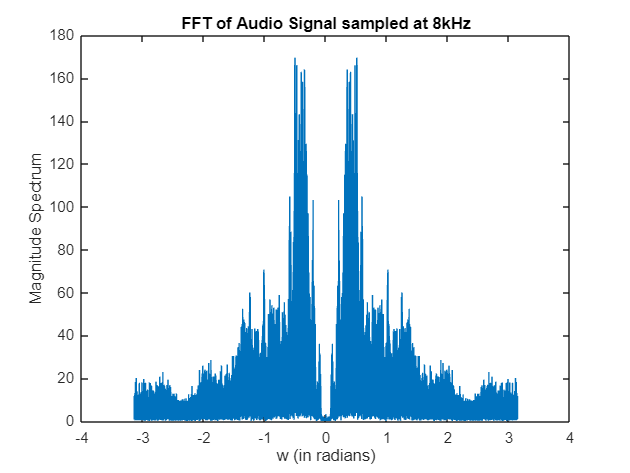

[x1,Fs1] = audioread("speech8khz.wav");
L1 = 80000;
X1 = fft(x1);
X1 = fftshift(X1);
w1 = (-L1/2:L1/2-1) * (2*pi/L1);
plot(w1,abs(X1)); 
title('FFT of Audio Signal sampled at 8kHz')
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

sound(x1,Fs1);

Now, we will process the Music Signal sampled at 16kHz.

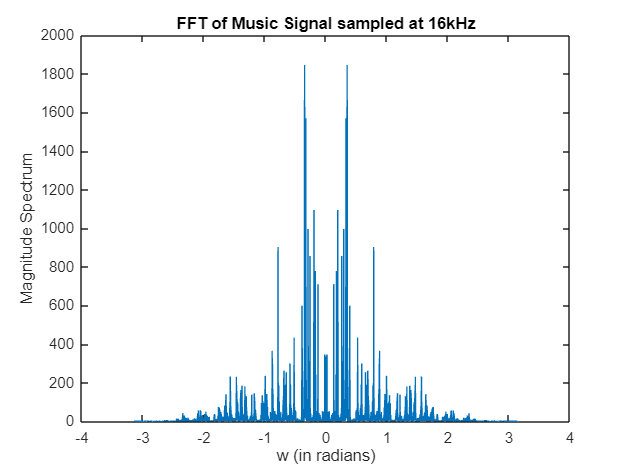

[x2,Fs2] = audioread("music16khz.wav");
L2 = 160000;
X2 = fft(x2);
X2 = fftshift(X2);
w2 = (-L2/2:L2/2-1) * (2*pi/L2);
plot(w2,abs(X2));
title('FFT of Music Signal sampled at 16kHz')
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

sound(x2,Fs2);

The next step is to create the filter $H_0(z)$ with specifications defined below - 

- 
$$\omega_p = 0.45 \pi$$


- 
$$\omega_s = 0.55 \pi$$


- Type-2 linear phase equiripple LPF

The function [firpmord](https://in.mathworks.com/help/signal/ref/firpmord.html) has been used in creating the required LPF. 

Since the passband and stop band ripple have been left unspecified, I will use 0.95 dB for passband ripple and 38 dB for stopband ripple. My roll number being EE21B019, I pick the last two digits of my roll number and divide it by 20 to set the passband ripple and multiply it by 2 to set the stop band ripple.  

For the speech signal, I shall design the filter below first, the notation used for this is H0_s.

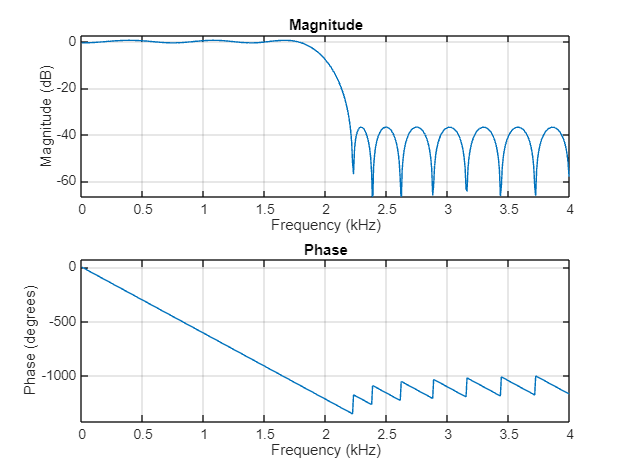

rp = 0.95;                    %Passband ripple (dB)
rs = 38;                      %Stopband ripple (dB)
dev = [(10^(rp/20)-1)/(10^(rp/20)+1) 10^(-rs/20)];   
a = [1 0];                    %Amplitudes of bands
fs = [1800 2200];         
[ns,fs0,as,ws] = firpmord(fs,a,dev,Fs1);
H0_s = firpm(ns,fs0,as,ws);
freqz(H0_s,1,512,Fs1);

Now for the music signal, I have designed the filter below. The notation used is H0_m

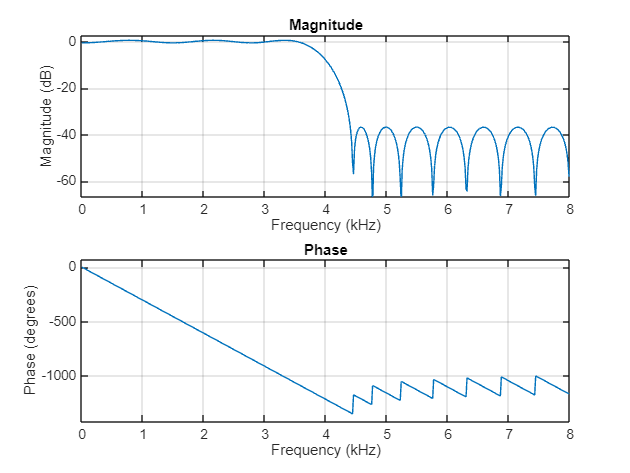

fm = [3600 4400];
[nm,fm0,am,wm] = firpmord(fm,a,dev,Fs2);
H0_m = firpm(nm,fm0,am,wm);
freqz(H0_m,1,512,Fs2);

The order of the filter obtained is 27. Thus, **N = 27**

Now, I shall proceed to find the polyphase components of both the filters. 

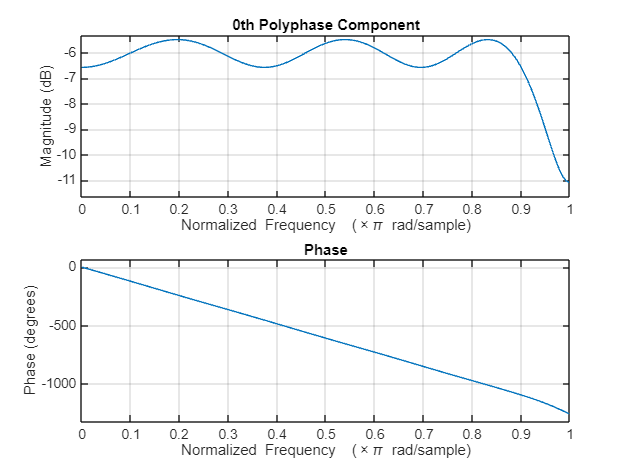

H00 = downsample(H0_m, 2);
freqz(H00);
title('0th Polyphase Component');

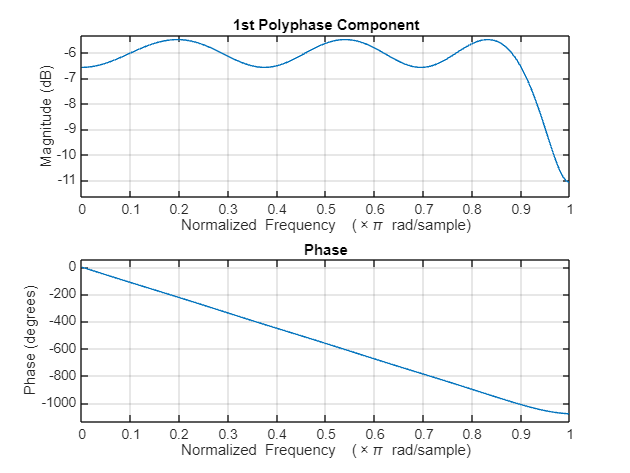

H0_delay = H0_m(2:end);
H01 = downsample(H0_delay,2);
freqz(H01);
title('1st Polyphase Component');

## Application of the Synthesis Filter Bank on the Signals

Following the notation used in the PDF, we have the following 

Here, I will use $x_1 $ to denote the speech signal and $x_2$ to denote the music signal.  

## Output of the Synthesis FB for $x_1$

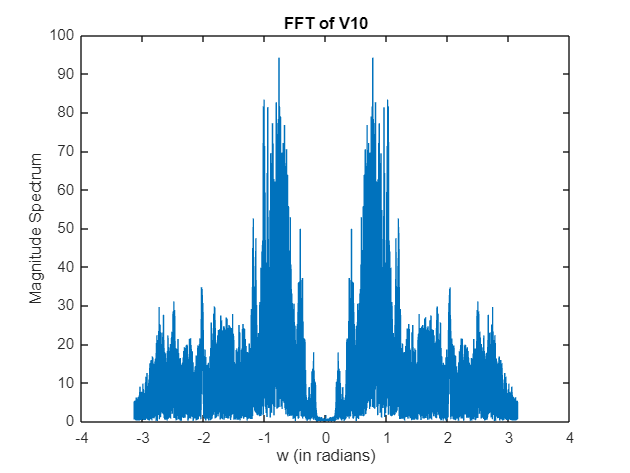

s1_d = downsample(x1, 2);
x1_delay = zeros(size(x1));
x1_delay(1:end-1) = x1(2:end);
x1_d = downsample(x1_delay,2);
t1_0 = conv(H00, x1_d);
t1_1 = conv(H01, s1_d);
vd1_0 = t1_0 + t1_1;
vd1_1 = t1_0 - t1_1;
Lv1d0 = 40013; 
V10 = fft(vd1_0);
V10 = fftshift(V10);
wv1d0 = (-Lv1d0/2:Lv1d0/2-1) * (2*pi/Lv1d0);
plot(wv1d0,abs(V10)); 
title('FFT of V10');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

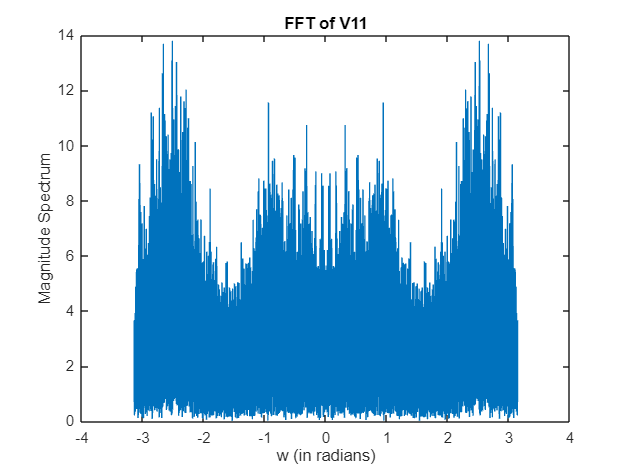

V11 = fft(vd1_1);
V11 = fftshift(V11);
plot(wv1d0,abs(V11)); 
title('FFT of V11');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

## Output of the Synthesis FB for $x_2$

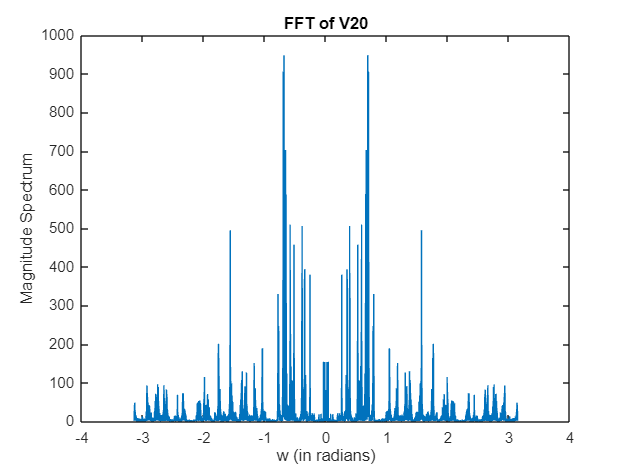

s2_d = downsample(x2, 2);
x2_delay = zeros(size(x2));
x2_delay(1:end-1) = x2(2:end);
x2_d = downsample(x2_delay,2);
t2_0 = conv(H00, x2_d);
t2_1 = conv(H01, s2_d);
vd2_0 = t2_0 + t2_1;
vd2_1 = t2_0 - t2_1;
Lv2d0 = 80013; 
V20 = fft(vd2_0);
V20 = fftshift(V20);
wv2d0 = (-Lv2d0/2:Lv2d0/2-1) * (2*pi/Lv2d0);
plot(wv2d0,abs(V20));
title('FFT of V20');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

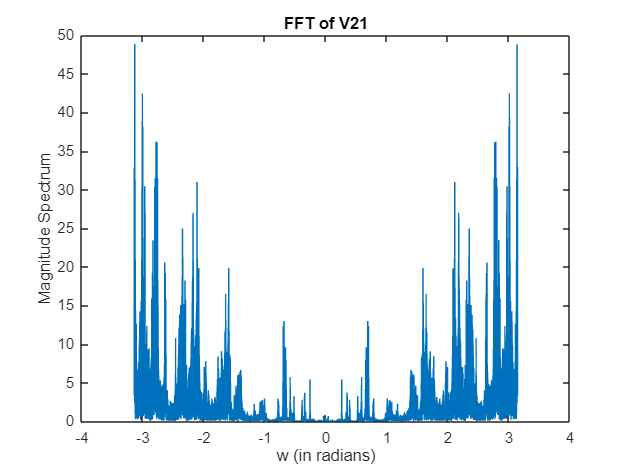

V21 = fft(vd2_1);
V21 = fftshift(V21);
plot(wv2d0,abs(V21)); 
title('FFT of V21');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

## Action of Analysis FB on the Signals

The action of the analysis filter bank can be represented as 

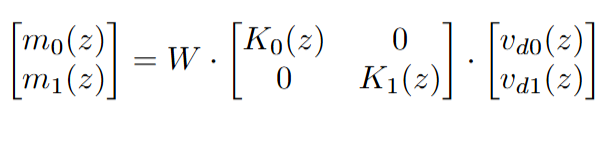

%Action on the speech signal
m1_0 = vd1_0 + vd1_1;
m1_1 = vd1_0 - vd1_1;
%Action on the music signal
m2_0 = vd2_0 + vd2_1;
m2_1 = vd2_0 - vd2_1;

## Case 1 : $K_0(z) = H_{01}(z)$ and $K_1(z) = H_{00}(z)$

In this case, 


$$T(z) = z^{-1} S(z) \text{ and } A(z) = 0$$


where S(z) is given by


$$S(z) = H_{00}(z)H_{01}(z)$$


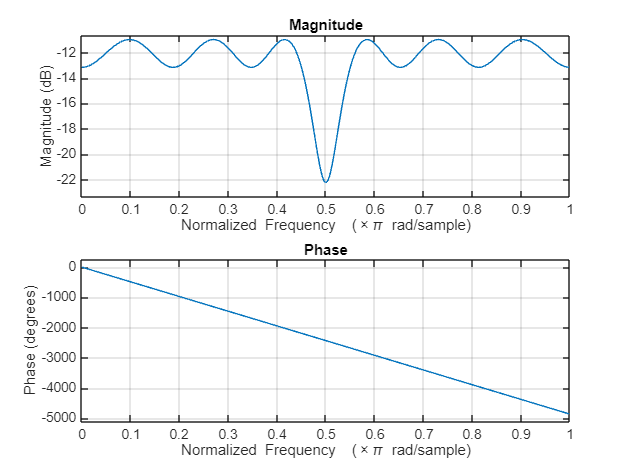

s = conv(H00,H01);
s_up = upsample(s,2);
t = [0, s_up(1:end)];
freqz(t);

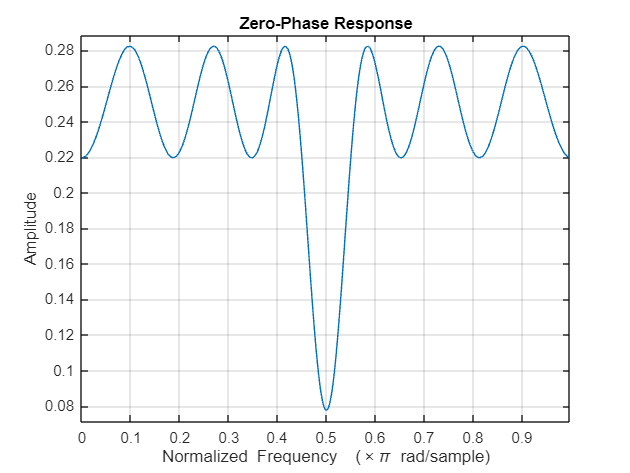

zerophase(t);

## Filtering the Speech Signal

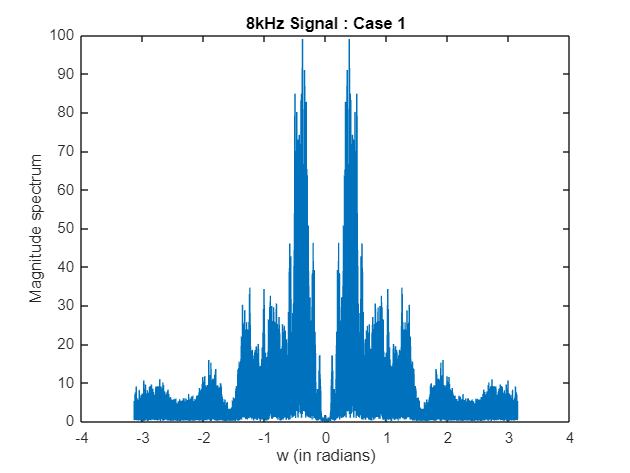

ws1_0 = conv(H01,m1_0);
ws1_1 = conv(H00,m1_1);
wup1_0 = upsample(ws1_0,2);
wup1_1 = upsample(ws1_1,2);
ts11 = [0 ; wup1_0];
ts12 = [wup1_1 ; 0];
ys1 = ts12 + ts11;
Ls1 = 80053;
Ys1 = fft(ys1);
Ys1 = fftshift(Ys1);
ws1 = (-Ls1/2:Ls1/2-1) * (2*pi/Ls1);
plot(ws1,abs(Ys1));
title('8kHz Signal : Case 1');
xlabel('w (in radians)');
ylabel('Magnitude spectrum');

sound(ys1, Fs1);

## Observations

- As expected, this set of filters$K_0(z) \text{ and } K_1(z) $ do not result in Aliasing. 

- There is hardly any difference between the output audio and the input audio. 

## Filtering the Music Signal

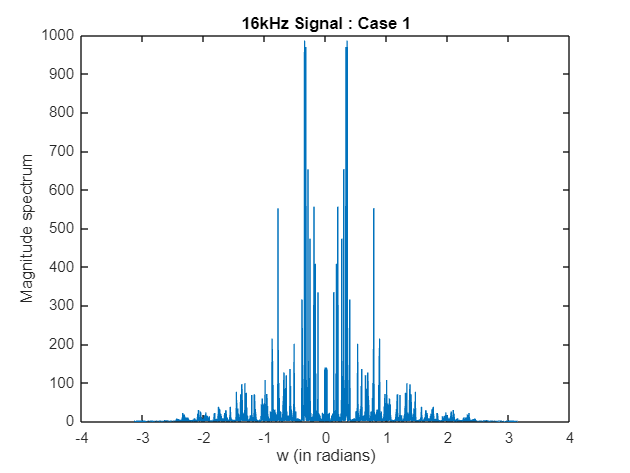

wm1_0 = conv(H01,m2_0);
wm1_1 = conv(H00,m2_1);
wmup1_0 = upsample(wm1_0,2);
wmup1_1 = upsample(wm1_1,2);
tm11 = [0 ; wmup1_0];
tm12 = [wmup1_1 ; 0];
ym1 = tm12 + tm11;
Lm1 = 160053;
Ym1 = fft(ym1);
Ym1 = fftshift(Ym1);
wm1 = (-Lm1/2:Lm1/2-1) * (2*pi/Lm1);
plot(wm1,abs(Ym1));
title('16kHz Signal : Case 1');
xlabel('w (in radians)');
ylabel('Magnitude spectrum');

sound(ym1, Fs2);

## Observations

- As expected, this set of filters$K_0(z) \text{ and } K_1(z) $ do not result in Aliasing. 

- There is hardly any difference between the output audio and the input audio. 

## Case 1 : $K_0(z) = H_{00}(z)$ and $K_1(z) = H_{01}(z)$

In this case, 


$$A(z) \neq 0$$


## Filtering the Speech Signal

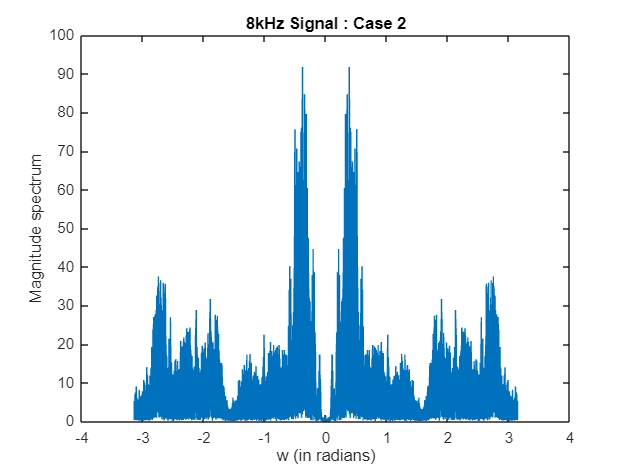

ws2_0 = conv(H00,m1_0);
ws2_1 = conv(H01,m1_1);
wup2_0 = upsample(ws2_0,2);
wup2_1 = upsample(ws2_1,2);
ts21 = [0 ; wup2_0];
ts22 = [wup2_1 ; 0];
ys2 = ts22 + ts21;
Ls2 = 80053;
Ys2 = fft(ys2);
Ys2 = fftshift(Ys2);
ws2 = (-Ls2/2:Ls2/2-1) * (2*pi/Ls2);
plot(ws2,abs(Ys2));
title('8kHz Signal : Case 2');
xlabel('w (in radians)');
ylabel('Magnitude spectrum');

sound(ys2, Fs1);

## Observations

- As expected, this set of filters$K_0(z) \text{ and } K_1(z) $ result in significant aliasing.. 

- There is output audio is not clear. 

## Filtering the Music Signal

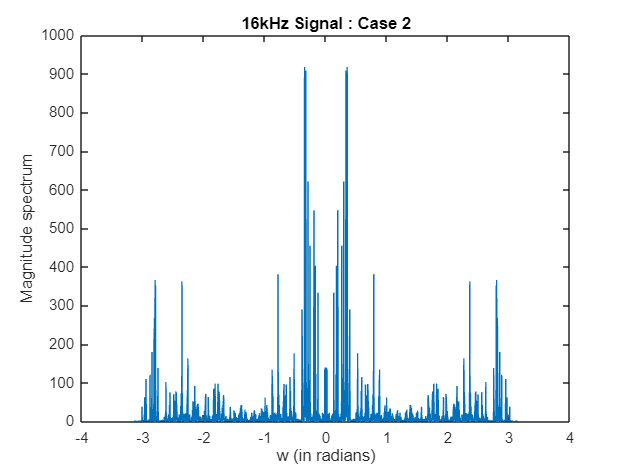

wm2_0 = conv(H00,m2_0);
wm2_1 = conv(H01,m2_1);
wmup2_0 = upsample(wm2_0,2);
wmup2_1 = upsample(wm2_1,2);
tm21 = [0 ; wmup2_0];
tm22 = [wmup2_1 ; 0];
ym2 = tm22 + tm21;
Lm2 = 160053;
Ym2 = fft(ym2);
Ym2 = fftshift(Ym2);
wm2 = (-Lm2/2:Lm2/2-1) * (2*pi/Lm2);
plot(wm2,abs(Ym2));
title('16kHz Signal : Case 2');
xlabel('w (in radians)');
ylabel('Magnitude spectrum');

sound(ym2, Fs2);

## Observations

- As expected, this set of filters$K_0(z) \text{ and } K_1(z) $ result in significant aliasing.. 

- There is output audio is not clear. 